# **EEE-3102: Numerical Technique Laboratory**

# **Lab-04: Determination** **of** **model** **parameters** **by** **fitting** **nonlinear data ****with** **a specific** **function.**

**Lab Group- B**

#### **Name: M. Ashikuzzaman Kowshik**

#### **Class roll: AE-073-051**

### **Example-1: **For this, try the following code:

clc;close all;
x=0:0.01:5; 
y=2*x.^2+3*x+4;             % x and y data
db=30; 
yo=awgn(y,db,'measured');   % noisy data

#### **Q.1:     **(i) What are the model parameters?

ap=polyfit(x,yo,2)          % model parameters for n=2

ap =     2.0004    2.9469    4.1808


####             (ii) What is the MSE?

yp=polyval(ap,x);           % fitted data
MSEp=mean((yo-yp).^2)       % MSE

MSEp = 1.1077

### **Example-2**: Now try the  following code which is simply followed by the code in **example-1**.

clc;close all;
x=0:0.01:5; 
y=2*x.^2+3*x+4;                     % x and y data
db=30; 
yo=awgn(y,db,'measured');           % noisy data

%%%% polyfit %%%%%
ap=polyfit(x,yo,2);                 % model parameters for n=2
yp=polyval(ap,x);                   % fitted data
MSEp=mean((yo-yp).^2);              % MSE

%%% lsqcurvefit %%%%%%%
F = @(a,x)(a(1)*x.^2+a(2)*x+a(3));  % 2nd order polynomial
ai=[1 1 1];                         % model parameters
[al] = lsqcurvefit(F,ai,x,yo);      % model parameters


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


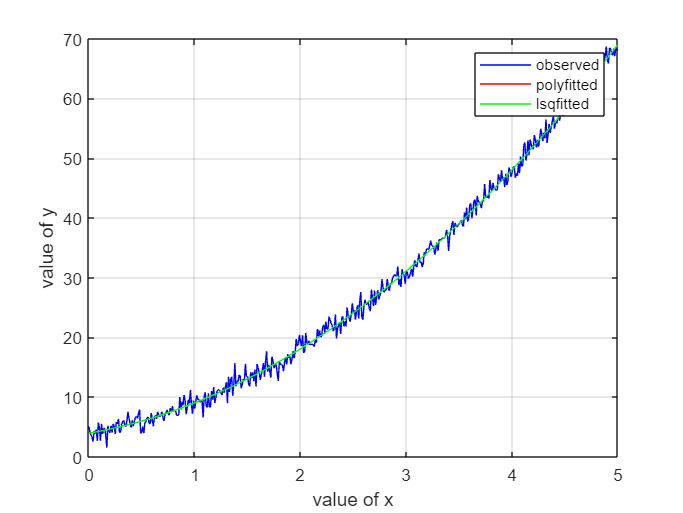

yl = F(al,x);                         %Fitted data
MSEl=mean((yo-yl).^2);              % MSE

figure;
plot(x,yo,'b',x,yp,'r',x,yl,'g')
xlabel('value of x'); 
ylabel('value of y');
legend('observed','polyfitted','lsqfitted');
grid on

#### Exercise- 01: A Gaussian distribution function is given by $y=ae^{-{\left(x-b\right)}^2 /2c^2 } \;$. Let a = 10, b = 50 and c = 10 for 0$\le$x$\le$100 with a step of 0.1. Add noise to y and produce yo such that SNR = 30 dB.

####     i) Draw a graph to show the ‘yo’ and polyfitted data ‘yp’ versus ‘x’ in a plot for n = 2. What is the MSE?

clc;close all;
x = 0 : 0.1: 100;
a=10;
b=50;
c=10;
n=10;
y= a* exp(-(x-b).^2/(2*c.^2));
SNR=30;

y0 = awgn(y, SNR, 'measured')

y0 =     0.0478   -0.1057   -0.0302    0.2121    0.0207    0.0238   -0.0449   -0.2029   -0.0943   -0.1153    0.0096    0.0208   -0.0242    0.0973   -0.0462    0.0313   -0.1154   -0.1307   -0.0390    0.1098    0.0259    0.0397   -0.0944   -0.0914    0.0763    0.0594   -0.1763   -0.1994    0.1353   -0.0035   -0.0212    0.0506   -0.0141    0.0285    0.0625   -0.2148    0.0022   -0.0048    0.0540    0.0409   -0.1652    0.0178   -0.1327   -0.0468    0.0144    0.1275    0.0622    0.0358   -0.1890    0.0152


ap = polyfit(x, y0, n)

ap =    -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0022    0.0303   -0.2140    0.6232   -0.4417


yp = polyval(ap, x)

yp =    -0.4417   -0.3815   -0.3254   -0.2732   -0.2248   -0.1800   -0.1386   -0.1005   -0.0655   -0.0335   -0.0043    0.0221    0.0460    0.0674    0.0865    0.1034    0.1182    0.1311    0.1420    0.1512    0.1588    0.1648    0.1693    0.1724    0.1743    0.1750    0.1745    0.1730    0.1705    0.1671    0.1629    0.1580    0.1523    0.1460    0.1392    0.1318    0.1240    0.1158    0.1072    0.0983    0.0891    0.0797    0.0701    0.0604    0.0506    0.0407    0.0308    0.0209    0.0110    0.0012


MSE = mean((y0-yp).^2)

MSE = 0.0380

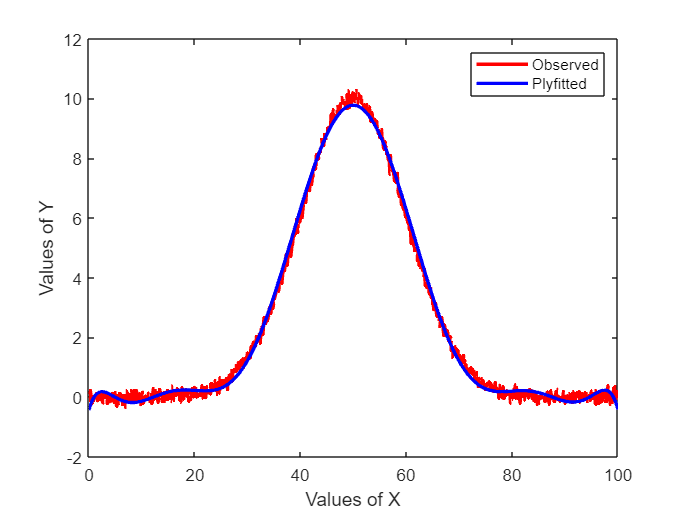


figure;
plot(x, y0, 'r-', x, yp, 'b-', 'LineWidth', 2)
xlabel('Values of X')
ylabel('Values of Y')
legend('Observed', 'Plyfitted')

####     v) Fit the data sets using ‘polyfit’ function with different order of n = 1, 2 ….10 and plot a graph to show the variation of MSE with order ‘n’. What is the value of MSE for n=10?

clc;close all;clear all; 
x=0:0.1:100; 
a=10;
b=50;
c=10;
%e=exp(1); 
i = 0; 
y=a*exp(-(x-b).^2/(2*c.^2)); 
SNR=30; 
for n=1:10 
    y1=awgn(y,SNR,'measured'); 
    a=polyfit(x,y1,n); 
    ym=polyval(a,x); 
    i=i+1; 
    MSE(1,i)=mean((y1-ym).^2); 
end

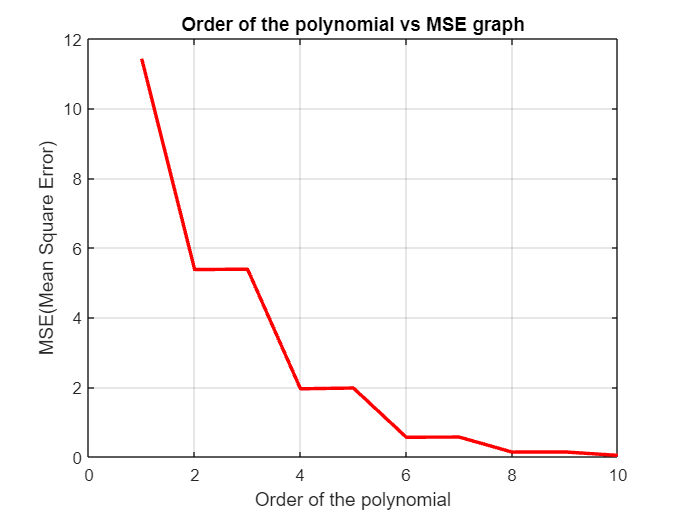


n=1:1:10; 
plot(n,MSE,'r','linewidth',2) 
grid on 
xlabel('Order of the polynomial') 
ylabel('MSE(Mean Square Error)') 
title('Order of the polynomial vs MSE graph') 

MSE= MSE(1,10)

MSE = 0.0371

clc;close all;clear all; 
n = 1:10

n =      1     2     3     4     5     6     7     8     9    10
